# CA1

## PART1

.سه سیگنال را لود کرده و آن ها را در حوزه زمان و فرکانس رسم میکنیم

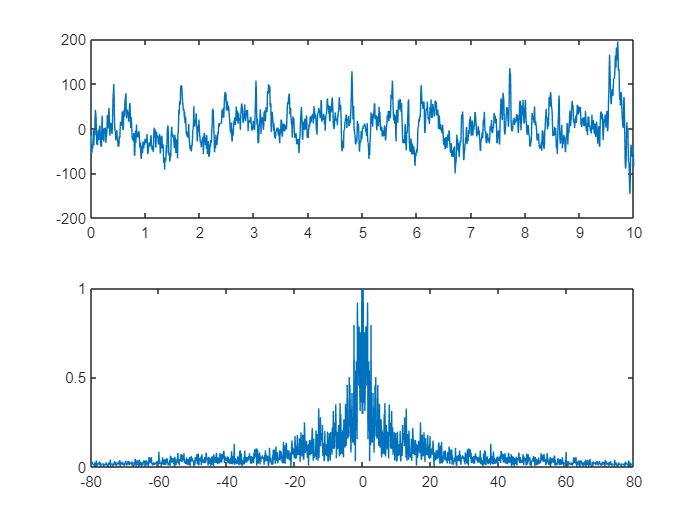

clc;clear;close all
load('v1.mat','val');
X1 = val(1, :);
L=length(X1);
fs=length(X1)/10;
t=0:1/fs:10-1/fs;
f=-fs/2:fs/L:fs/2-fs/L;

figure
subplot(2,1,1);
plot(t,real(X1));
X1f=ifftshift(fft(X1));
subplot(2,1,2);
plot(f,abs(X1f/max(X1f)));

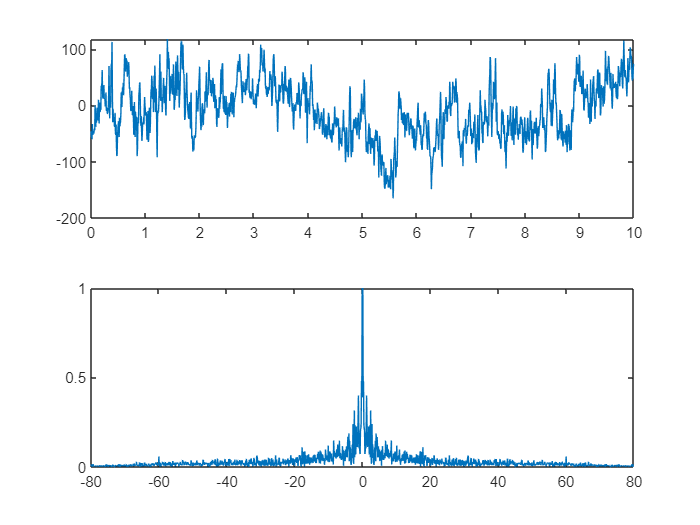

load('v2.mat','val');
X2= val(1, :);
figure
subplot(2,1,1);
plot(t,real(X2));
X2f=ifftshift(fft(X2));
subplot(2,1,2);
plot(f,abs(X2f/max(X2f)));

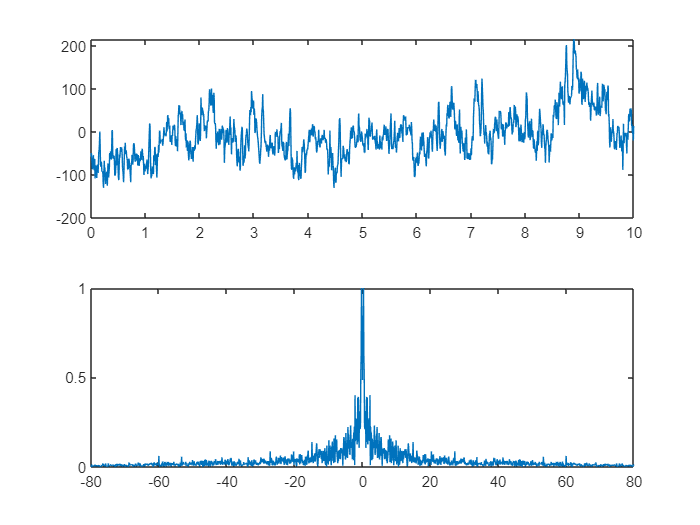

load('v3.mat','val');
X3= val(1, :);
figure
subplot(2,1,1);
plot(t,real(X3));
X3f=ifftshift(fft(X3));
subplot(2,1,2);
plot(f,abs(X3f/max(X3f)));

.با توجه به نتایج میتوان گفت با افزایش دامنه ، فرکانس کم میشود و این دو با یکدیگر رابطه عکس دارد

.حال  سیگنال ها را از فیلتر برای امواج متفاوت مغزی جدا میکنیم و آن ها را رسم میکنیم 

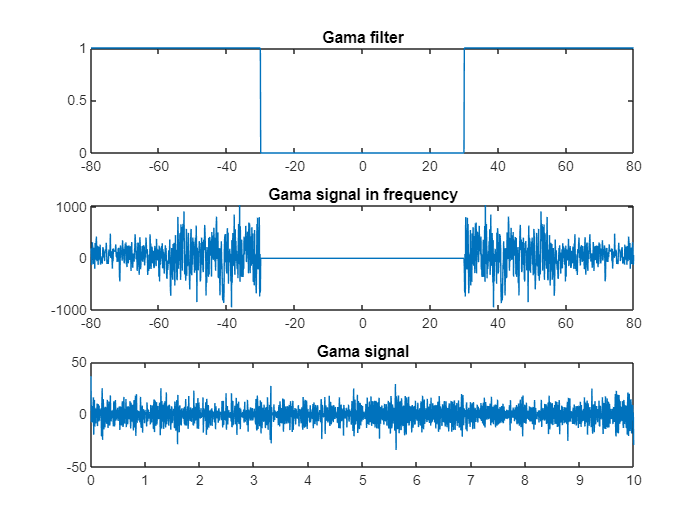

GamaX1=Gama(X1f,f,t);

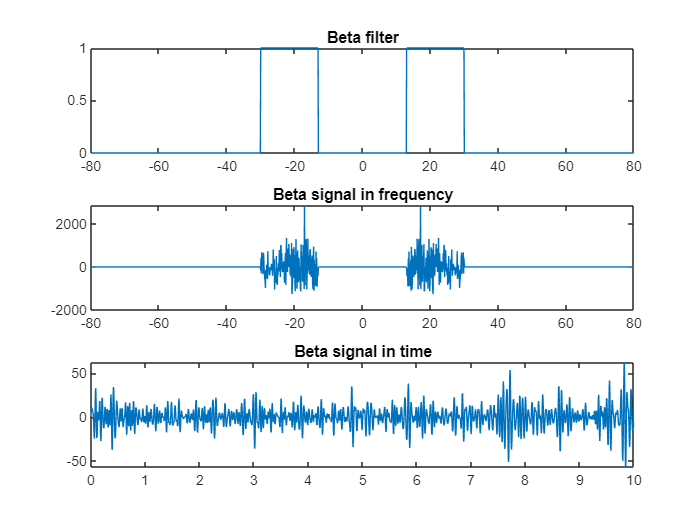

BetaX1=Beta(X1f,f,t);

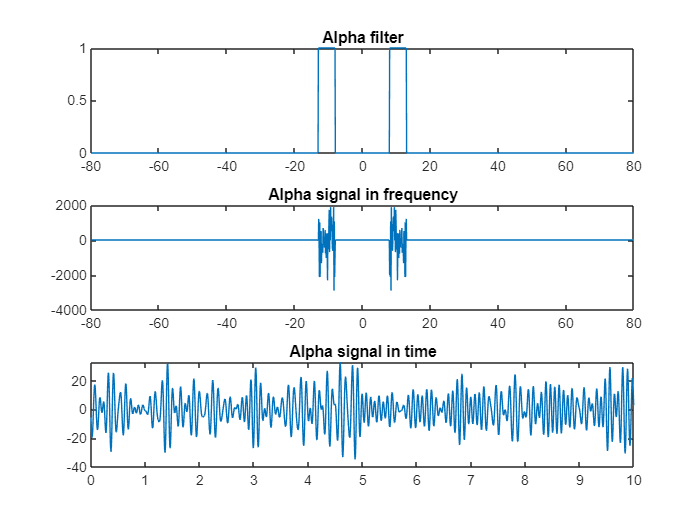

AlphaX1=Alpha(X1f,f,t);

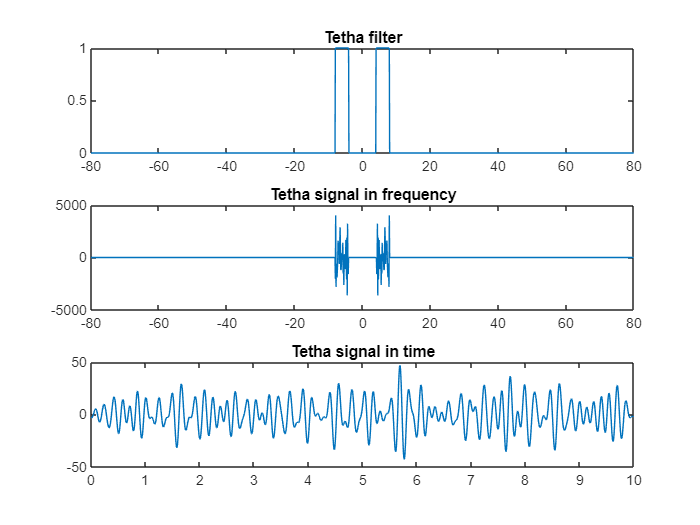

TethaX1=Tetha(X1f,f,t);

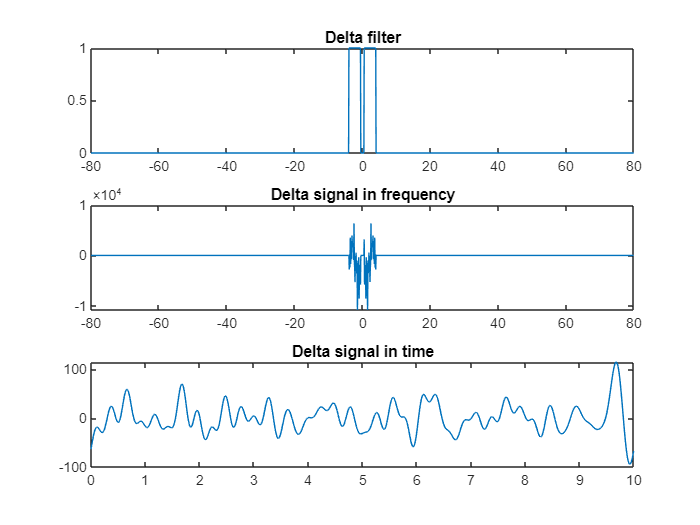

DeltaX1=Delta(X1f,f,t);

با توجه به نتایج به دست از فوریه و حوزه زمان میتوان گفت سیگنال غالب در این ده ثانیه امواج دلتا است اما با توجه به پیک های آن میتوان گفت فرکانس های دیگری نیز وجود دارد و برای مثال شخص در حال خواب دیدن است اما درباره خواب بودن شخص شکی نیست

.پس با توجه به فرکانس و پیک های زمانی میتوان به این نتیجه رسید

.مشکلی که در اینجا موجود هست سیگنال را باید با خود آن شخص مقابسه کرد و نمیتوان با داشتن سیگنال تنها به نتیجه رسید

Gama filtering

function GamaEEGt=Gama(Xf,f,t)
f1=stepfun(f,-80);
f2=stepfun(f,-30);
f3=stepfun(f,30);
filter=f1-f2+f3;
figure
subplot(3,1,1);
plot(f,filter);
title('Gama filter');

GamaEEGf=Xf.*filter;
subplot(3,1,2);
plot(f,GamaEEGf);
title('Gama signal in frequency');

GamaEEGt=ifft(ifftshift(GamaEEGf));
subplot(3,1,3);
plot(t,real(GamaEEGt))
title('Gama signal');
end

Beta filtering

function BetaEEGt=Beta(Xf,f,t)
f1=stepfun(f,-30);
f2=stepfun(f,-13);
f3=stepfun(f,13);
f4=stepfun(f,30);
filter=f1-f2+f3-f4;
figure
subplot(3,1,1);
plot(f,filter);
title('Beta filter');

BetaEEGf=Xf.*filter;
subplot(3,1,2);
plot(f,BetaEEGf);
title('Beta signal in frequency');

BetaEEGt=ifft(ifftshift(BetaEEGf));
subplot(3,1,3);
plot(t,real(BetaEEGt))
title('Beta signal in time');
end

Alpha filtering

function AlphaEEGt=Alpha(Xf,f,t)
f1=stepfun(f,-13);
f2=stepfun(f,-8);
f3=stepfun(f,8);
f4=stepfun(f,13);
filter=f1-f2+f3-f4;
figure
subplot(3,1,1);
plot(f,filter);
title('Alpha filter');

AlphaEEGf=Xf.*filter;
subplot(3,1,2);
plot(f,AlphaEEGf);
title('Alpha signal in frequency');

AlphaEEGt=ifft(ifftshift(AlphaEEGf));
subplot(3,1,3);
plot(t,real(AlphaEEGt))
title('Alpha signal in time');
end

Tetha filtering

function TethaEEGt=Tetha(Xf,f,t)
f1=stepfun(f,-8);
f2=stepfun(f,-4);
f3=stepfun(f,4);
f4=stepfun(f,8);
filter=f1-f2+f3-f4;
figure
subplot(3,1,1);
plot(f,filter);
title('Tetha filter');

TethaEEGf=Xf.*filter;
subplot(3,1,2);
plot(f,TethaEEGf);
title('Tetha signal in frequency');

TethaEEGt=ifft(ifftshift(TethaEEGf));
subplot(3,1,3);
plot(t,real(TethaEEGt))
title('Tetha signal in time');
end

Delta filtering

function DeltaEEGt=Delta(Xf,f,t)
f1=stepfun(f,-4);
f2=stepfun(f,-0.5);
f3=stepfun(f,0.5);
f4=stepfun(f,4);
filter=f1-f2+f3-f4;
figure
subplot(3,1,1);
plot(f,filter);
title('Delta filter');

DeltaEEGf=Xf.*filter;
subplot(3,1,2);
plot(f,DeltaEEGf);
title('Delta signal in frequency');

DeltaEEGt=ifft(ifftshift(DeltaEEGf));
subplot(3,1,3);
plot(t,real(DeltaEEGt))
title('Delta signal in time');
end